Define function and plot the analytical derivatives

f=@(x)exp(-(x-10).^2).*cos(6*(x-10))

f = function_handle with value:
    @(x)exp(-(x-10).^2).*cos(6*(x-10))


df=@(x)-2.*(x-10).*exp(-(x-10).^2).*cos(6*(x-10))-6.*exp(-(x-10).^2).*sin(6*(x-10))

df = function_handle with value:
    @(x)-2.*(x-10).*exp(-(x-10).^2).*cos(6*(x-10))-6.*exp(-(x-10).^2).*sin(6*(x-10))


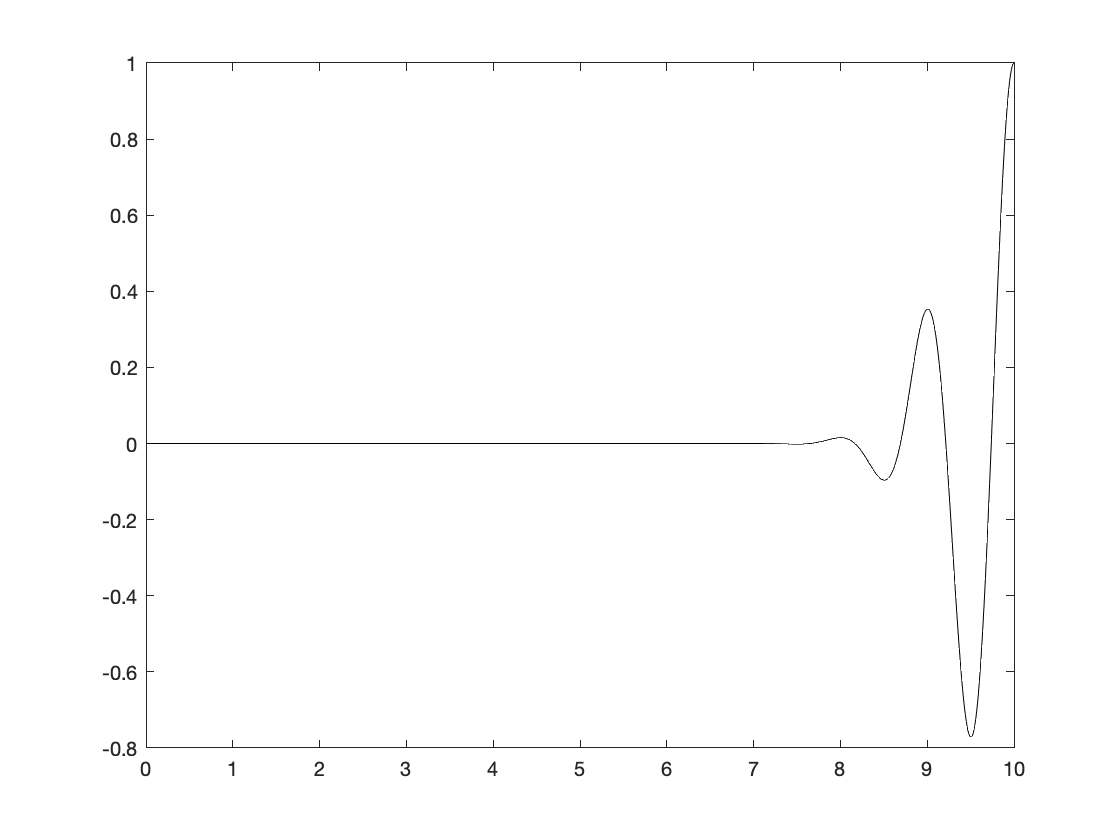

xveryfine=linspace(0,10,1000);

plot(xveryfine,f(xveryfine),'k-')

Ilustrate Grid with r=1.0 (equally spaced grid)

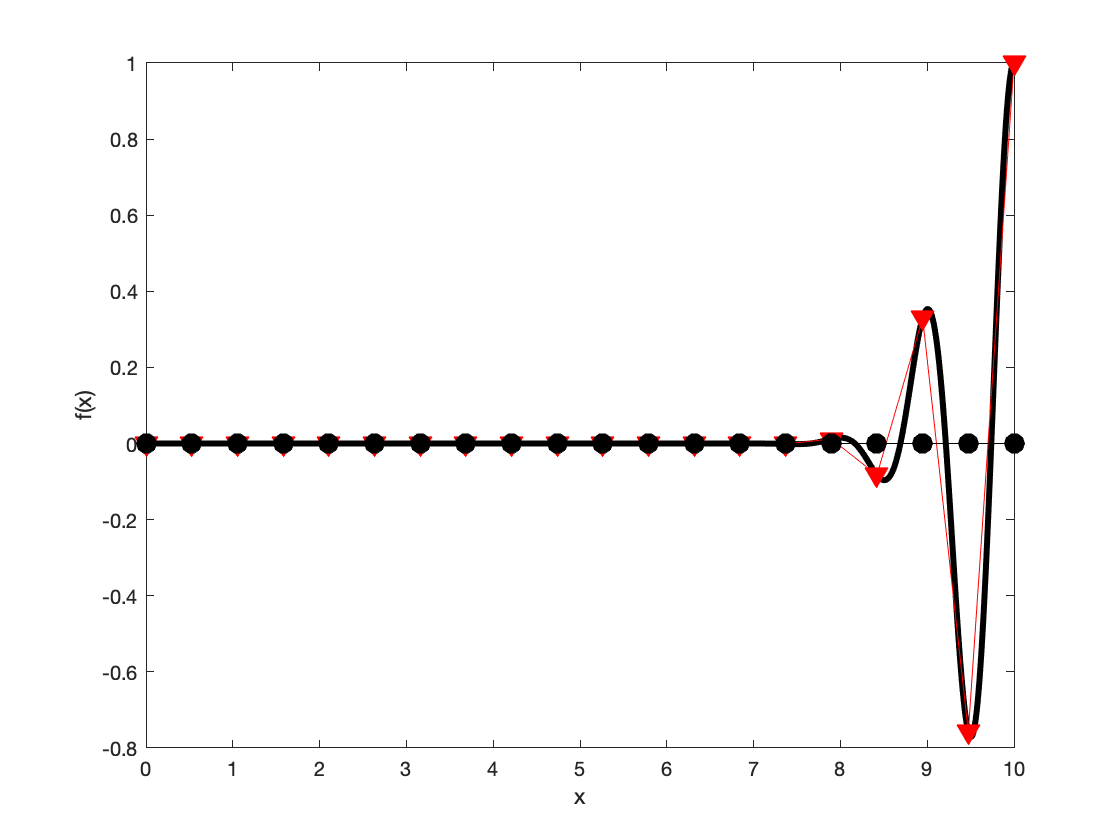

xi=GenGrid(0,10,20,1.0);
fi=f(xi);
h=plot(xveryfine,f(xveryfine),'k-',xi,fi,'rv-',xi,zeros(size(xi)),'ko-');
set(h(1),'linewidth',3);set(h(2),'Markersize',10,'Markerfacecolor',[1 0 0]);set(h(3),'Markersize',10,'Markerfacecolor',[0 0 0])
xlabel('x');ylabel('f(x)')

Ilustrate Grid with r=0.9 (not equally spaced grid)

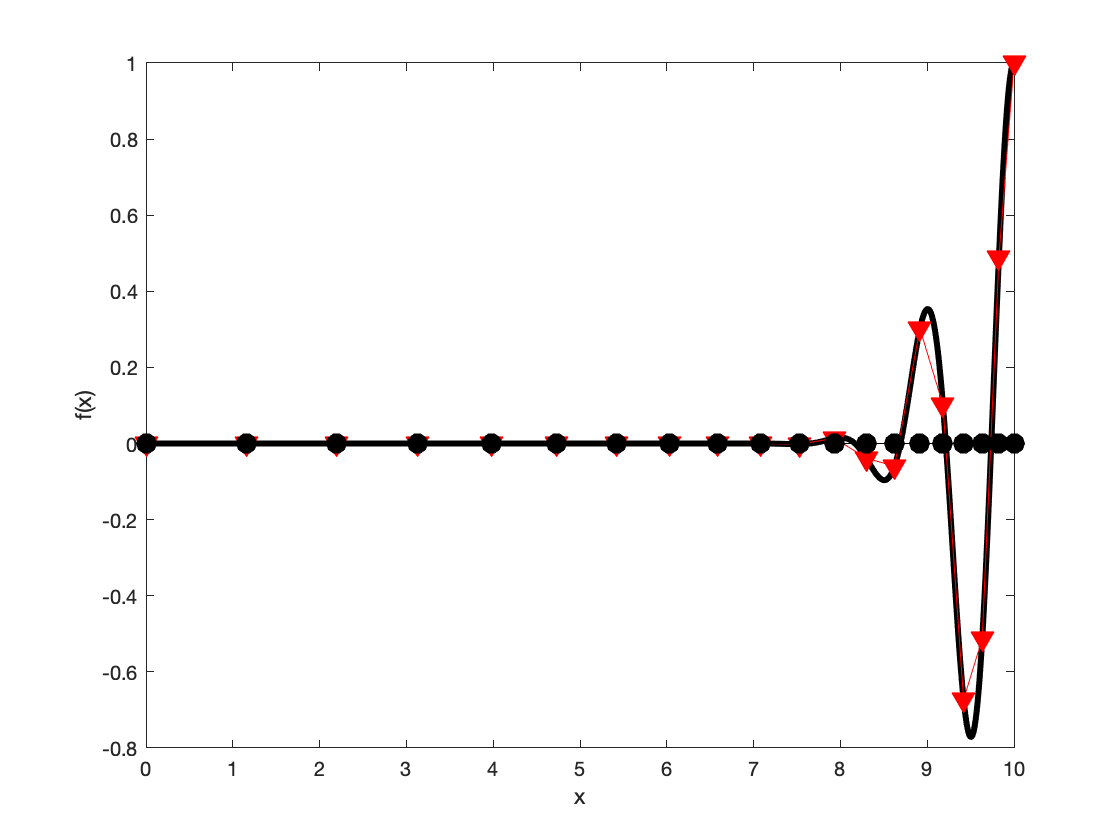

xi=GenGrid(0,10,20,0.9);
fi=f(xi);
h=plot(xveryfine,f(xveryfine),'k-',xi,fi,'rv-',xi,zeros(size(xi)),'ko-');
set(h(1),'linewidth',3);set(h(2),'Markersize',10,'Markerfacecolor',[1 0 0]);set(h(3),'Markersize',10,'Markerfacecolor',[0 0 0])
xlabel('x');ylabel('f(x)')

Equally spaced grid

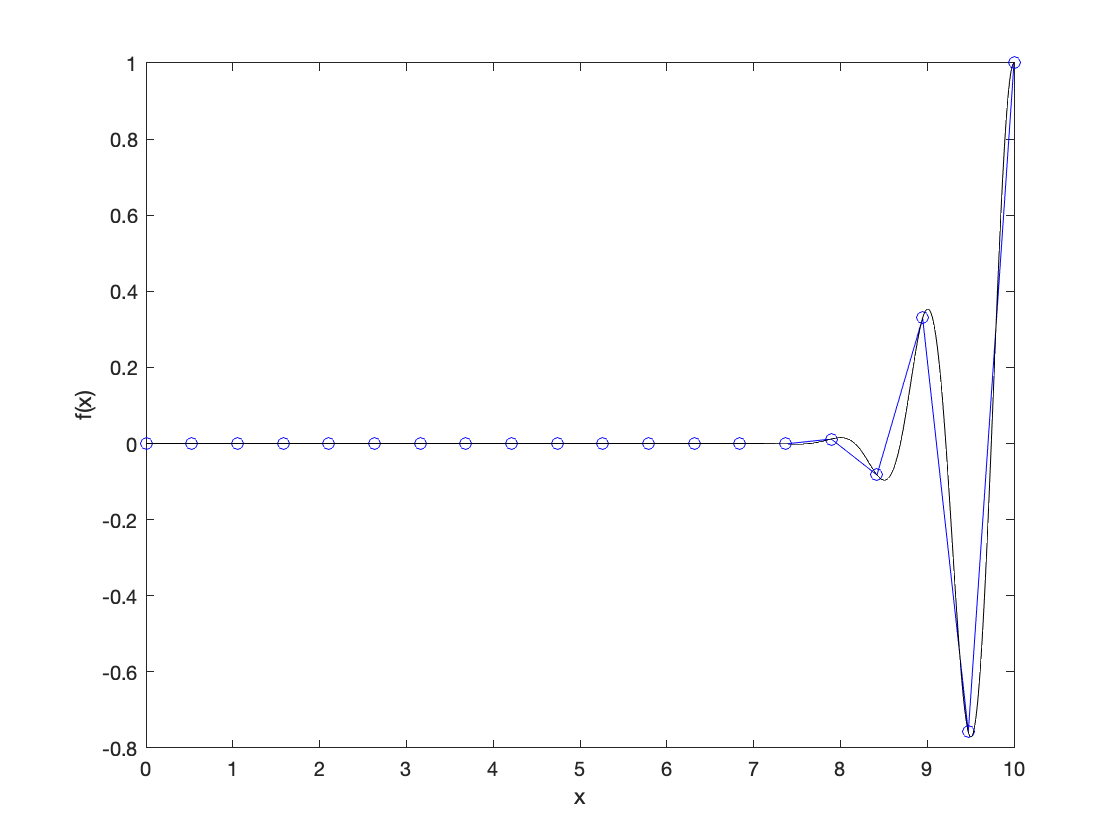

xi=GenGrid(0,10,20,1.0);
fi=f(xi);
dfi=DerivCDA(fi,xi);

plot(xi,fi,'bo-',xveryfine,f(xveryfine),'k-')
xlabel('x');ylabel('f(x)')

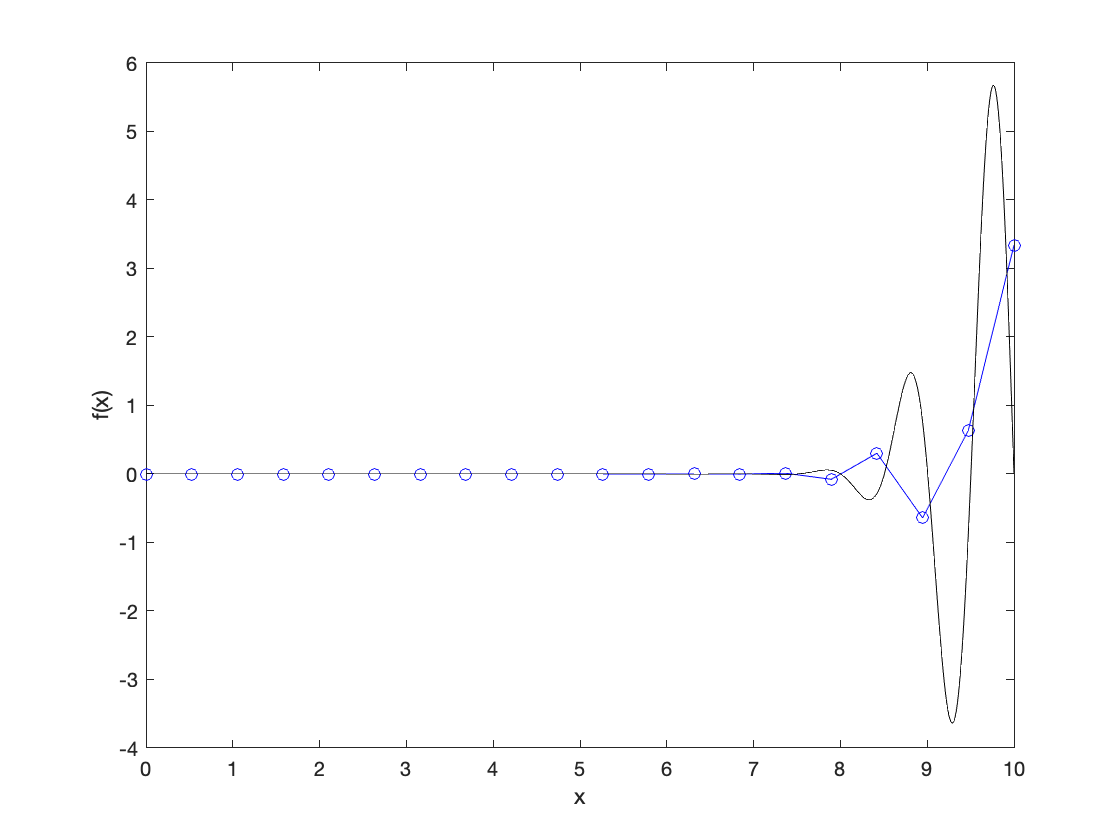


plot(xi,dfi,'bo-',xveryfine,df(xveryfine),'k-')
xlabel('x');ylabel('f(x)')

Refine mesh closer to x=10

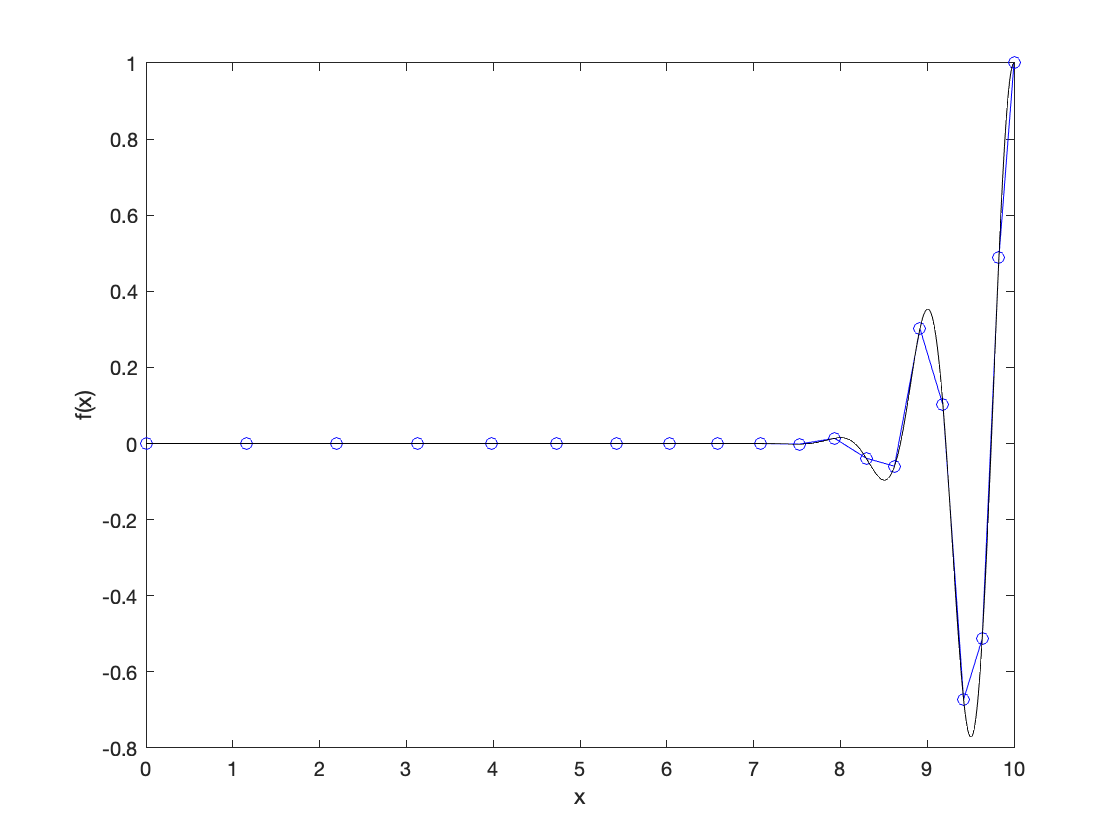

xi=GenGrid(0,10,20,0.9);
fi=f(xi);
dfi=DerivCDA(fi,xi);

plot(xi,fi,'bo-',xveryfine,f(xveryfine),'k-')
xlabel('x');ylabel('f(x)')

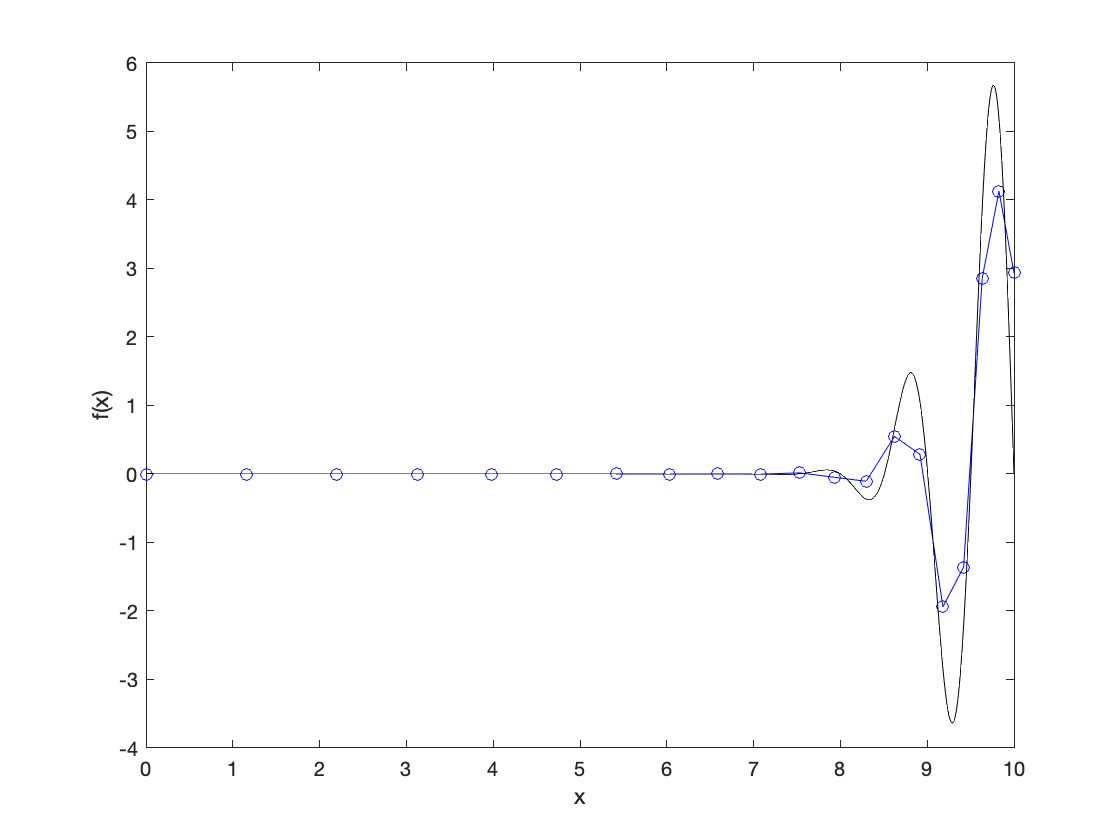


plot(xi,dfi,'bo-',xveryfine,df(xveryfine),'k-')
xlabel('x');ylabel('f(x)')

function df=DerivCDA(f,x)
df=zeros(size(f));
N=length(f);
df(1)=(f(2)-f(1))/(x(2)-x(1));
for i=2:N-1
    df(i)=(f(i+1)-f(i-1))/(x(i+1)-x(i-1));
end
df(N)=(f(N)-f(N-1))/(x(N)-x(N-1));
end

function x=GenGrid(a,b,N,r)
x=linspace(a,b,N);
if abs(r-1) > 1.0e-8
    dx0=(b-a)*(1-r)/(1-r.^(N-1));
    x(1)=a;
    dx=dx0;
    for i=2:N
        x(i)=x(i-1)+dx;
        dx=r*dx;
    end
end
end